%this generates the two_level sampling scheme in the paper- fig 8


%% Load signal
load('chirp_signal.mat', 'fd', 'td');
disp('Loaded existing signal vector from generated_signal.mat');

Loaded existing signal vector from generated_signal.mat



%% Sampling parameters
alpha1 = 0.09;
k1 = 2300;

alpha2 = 0.9;
k2 = 1;

Fm = 100;
c1 = 1;
shift = 4.2*c1;
BW = 2*pi*Fm;

%% Adaptive sampling
[tn, time_stamps, f_n, loc, NoF] = ...
    adaptive_sampling_running_func( ...
        fd, td, alpha1, alpha2, k1, k2, ...
        Fm, c1, shift);

disp(['Number of Firings: ', num2str(NoF)]);

Number of Firings: 136



NoF = length(time_stamps) - 1;

%% Reconstruction
iter = 25;

F_est = reconstruction_running_func( ...
    NoF, td, f_n-shift, ...
    time_stamps, loc, tn, ...
    BW, Fm, iter);

%% NMSE
nmse_db = 10*log10( ...
    norm(fd(50000:end-50000) - F_est(50000:end-50000,iter))^2 / ...
    norm(fd(50000:end-50000))^2 );

fprintf('NMSE = %.4f dB\n', nmse_db);

NMSE = -42.1332 dB



disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 5]


disp(['iter: ', num2str(iter)]);

iter: 5



%% Firing density
% Inter-spike intervals
isi = diff(tn);

% Instantaneous firing rate
firing_density = 1 ./ isi;

% Midpoint of each interval
firing_time = (tn(1:end-1) + tn(2:end))/2;


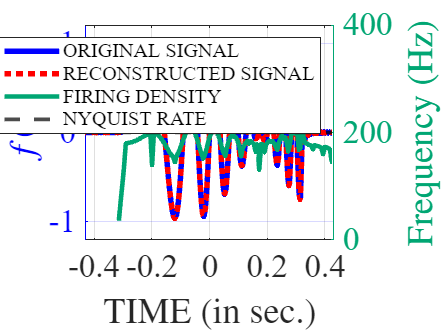


%% Plot: Signal, Reconstruction, and Firing Density

figure('Color','w');

%======================
% Left Axis
%======================
yyaxis left

plot(td, fd/c1, ...
    'b', ...
    'LineWidth', 3, ...
    'DisplayName', 'ORIGINAL SIGNAL');
hold on;

plot(td, F_est(:,iter)/c1, ...
    'r:', ...
    'LineWidth', 3, ...
    'DisplayName', 'RECONSTRUCTED SIGNAL');

ylabel('$f(t)$', ...
    'Interpreter','latex', ...
    'FontSize',18);

ylim([-1.2 1.2]);

ax = gca;
ax.YAxis(1).Color = [0 0 1];

%======================
% Right Axis
%======================
yyaxis right

plot(firing_time, firing_density, ...
    'Color', [0 0.65 0.45], ...
    'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');

hold on;

yline(2*Fm, ...
    'k--', ...
    'LineWidth', 2, ...
    'DisplayName', 'NYQUIST RATE');

ylabel('Frequency (Hz)', ...
    'Interpreter','latex', ...
    'FontSize',18);

ax.YAxis(2).Color = [0 0.65 0.45];

ylim([0 400])

%======================
% Formatting
%======================
xlabel('TIME (in sec.)', ...
    'Interpreter','latex', ...
    'FontSize',18);

xlim([-0.43 0.43]);

set(gca, ...
    'FontSize',18, ...
    'FontName','Times');

legend( ...
    'Location','northeast', ...
    'FontSize',11);

grid on;
box on;


% exportgraphics(gcf, ...
%     'adaptive_sampling_reconstruction.pdf', ...
%     'ContentType','vector', ...
%     'BackgroundColor','none', ...
%     'Resolution',300);
